# Descriptores.

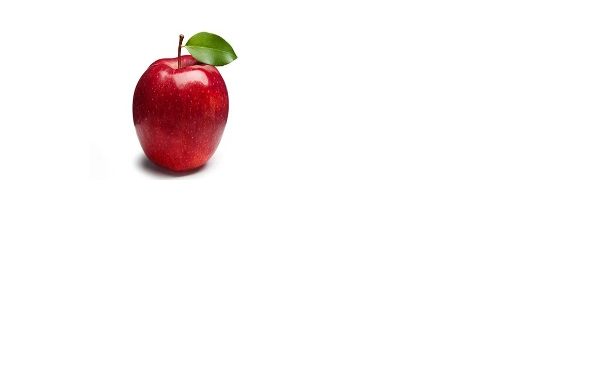

clc
close all
clear all

manzana1 = imread('M1.jpg');
manzana2 = imread('M2.jpg');
imagen = imread('I1.jpeg');

imshow(manzana1)

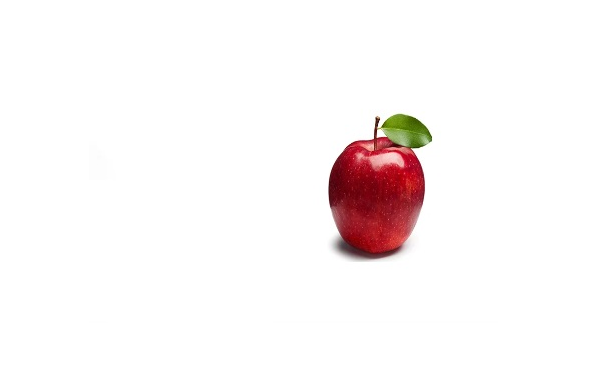

imshow(manzana2)

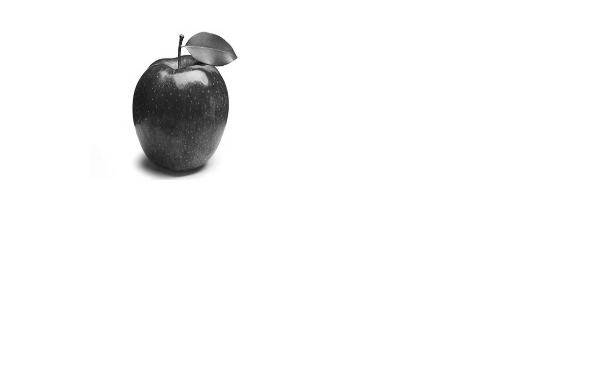


manzana1_gray = rgb2gray(manzana1);
manzana2_gray = rgb2gray(manzana2);
  imagen_gray = rgb2gray(imagen);

imshow(manzana1_gray)

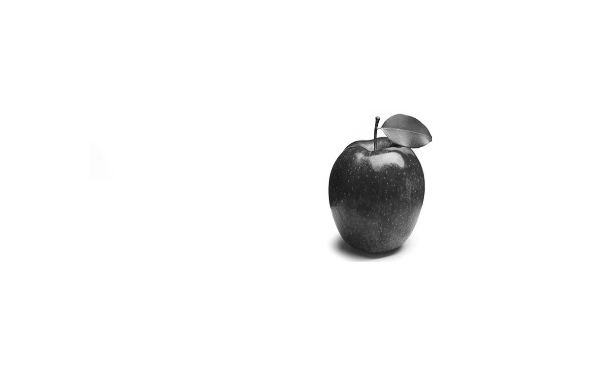

imshow(manzana2_gray)

size(manzana1_gray)

ans =    294   409


mean2(manzana1_gray)

ans = 239.0525

mean2(manzana2_gray)

ans = 239.0561

std2(manzana1_gray)

ans = 51.5721

std2(manzana2_gray)

ans = 51.5615

## Convolucion 2D

entrada(filas,columnas)

% salida(2,2) =   entrada(1,1) * kernel(1,1) + ... 
%                entrada(1,2) * kernel(1,2) + ...
%                entrada(1,3) * kernel(1,3) + ... 
%                entrada(2,1) * kernel(2,1) + ... 
%                entrada(2,2) * kernel(2,2) + ...
%                entrada(2,3) * kernel(2,3) + ...
%                entrada(3,1) * kernel(3,1) + ... 
%                entrada(3,2) * kernel(3,2) + ...
%                entrada(3,3) * kernel(3,3) 

entrada $\left\lbrack \begin{array}{ccccc}
\left(1,1\right) & \left(1,2\right) & \left(1,3\right) & \left(1,4\right) & \left(1,5\right)\\
\left(2,1\right) & \left(2,2\right) & \left(2,3\right) & \left(2,4\right) & \left(2,5\right)\\
\left(3,1\right) & \left(3,2\right) & \left(3,3\right) & \left(3,4\right) & \left(3,5\right)\\
\left(4,1\right) & \left(4,2\right) & \left(4,3\right) & \left(4,4\right) & \left(4,5\right)\\
\left(5,1\right) & \left(5,2\right) & \left(5,3\right) & \left(5,4\right) & \left(5,5\right)
\end{array}\right\rbrack$

kernel $\left\lbrack \begin{array}{ccc}
\left(1,1\right) & \left(1,2\right) & \left(1,3\right)\\
\left(2,1\right) & \left(2,2\right) & \left(2,3\right)\\
\left(3,1\right) & \left(3,2\right) & \left(3,3\right)
\end{array}\right\rbrack$

entrada = [ -4  0 -2  4  1;
             3  1  0  2  1;
             1  0  1  1  1;
             4  6  5  1  0;
            -1  2  0  0  0]

entrada =     -4     0    -2     4     1
     3     1     0     2     1
     1     0     1     1     1
     4     6     5     1     0
    -1     2     0     0     0


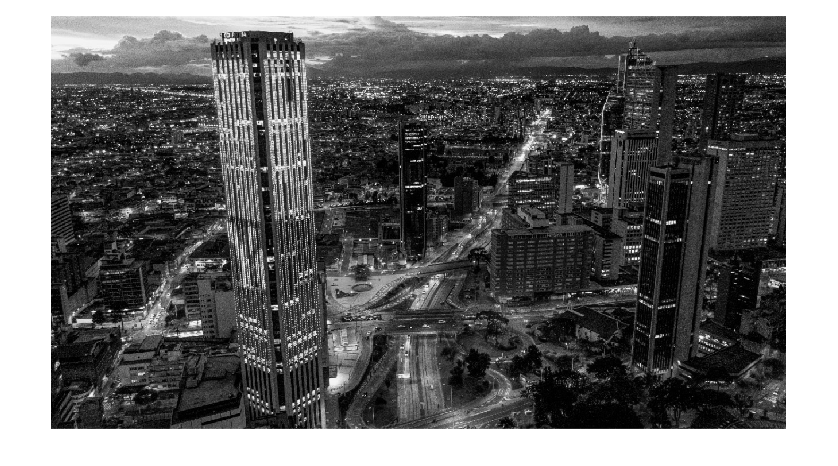

kernel = [-2 -1  0; -1  1  1; 0  1  2]; 

k1 = [ 1  2  1 ;  0  0  0 ; -1 -2 -1]; % Sobel C
k2 = [-1  0  1 ; -2  0  2 ;  1  0  1]; % Sobel F

activacion = "relu";

salida_conv_C1 = convolucion(imagen_gray,k1);
salida_actA_C1 = funcion_activacion(salida_conv_C1,activacion);
salida_conv_C1 = convolucion(imagen_gray,k2);
salida_actB_C1 = funcion_activacion(salida_conv_C1,activacion);

modo = "Min";

salA_pooling_C1 = polling(salida_actA_C1, 10, 10,modo);
salB_pooling_C1 = polling(salida_actB_C1, 10, 10,modo);

imshow(imagen_gray);

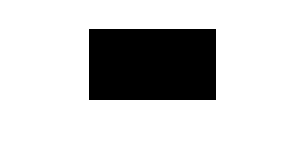

imshow(salA_pooling_C1);

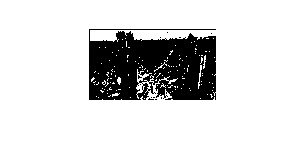

imshow(salB_pooling_C1);

salida_conv_C2 = convolucion(salA_pooling_C1,k1);
salida_actA_C2 = funcion_activacion(salida_conv_C2,activacion);
salida_conv_C2 = convolucion(salA_pooling_C1,k2);
salida_actB_C2 = funcion_activacion(salida_conv_C2,activacion);

salA_pooling_C2 = polling(salida_actA_C2, 10, 10,modo);
salB_pooling_C2 = polling(salida_actB_C2, 10, 10,modo);

salida_conv_C2 = convolucion(salB_pooling_C1,k1);
salida_actC_C2 = funcion_activacion(salida_conv_C2,activacion);
salida_conv_C2 = convolucion(salB_pooling_C1,k2);
salida_actD_C2 = funcion_activacion(salida_conv_C2,activacion);

salC_pooling_C2 = polling(salida_actC_C2, 10, 10,modo);
salD_pooling_C2 = polling(salida_actD_C2, 10, 10,modo);

imshow(salida_actA_C2);

imshow(salida_actB_C2);

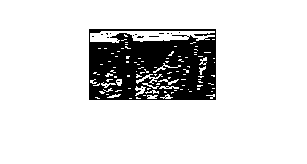

imshow(salida_actC_C2);

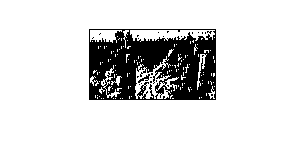

imshow(salida_actD_C2);


[filas, columnas] = size(salC_pooling_C2)

filas = 7

columnas = 12



for i=0: filas-1
    for j=1 : columnas
        interA((columnas*i)+j) = salA_pooling_C2(i+1,j);
    end
end

for i=0: filas-1
    for j=1 : columnas
        interB((columnas*i)+j) = salB_pooling_C2(i+1,j);
    end
end

for i=0: filas-1
    for j=1 : columnas
        interC((columnas*i)+j) = salC_pooling_C2(i+1,j);
    end
end

for i=0: filas-1
    for j=1 : columnas
        interD((columnas*i)+j) = salD_pooling_C2(i+1,j);
    end
end

interconexion = [interA interB interC interD]

interconexion =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## Funcion de convolucion. 

function salida = convolucion(imagen, kernel)

    entrada = int32(imagen);
    
    [filas, columnas] = size(entrada);
    salida = zeros(filas,columnas);

    for i=2: filas - 1
        for j=2: columnas - 1
            salida(i,j) = (entrada(i-1,j-1) * kernel(1,1)) + ... 
                          (entrada(i-1,j  ) * kernel(1,2)) + ...
                          (entrada(i-1,j+1) * kernel(1,3)) + ... 
                          (entrada(i  ,j-1) * kernel(2,1)) + ... 
                          (entrada(i  ,j  ) * kernel(2,2)) + ...
                          (entrada(i  ,j+1) * kernel(2,3)) + ...
                          (entrada(i+1,j-1) * kernel(3,1)) + ... 
                          (entrada(i+1,j  ) * kernel(3,2)) + ...
                          (entrada(i+1,j+1) * kernel(3,3)); 
        end
    end

end

### Funcion de activacion 

function salida = funcion_activacion(imagen, tipo)

    [filas, columnas] = size(imagen);
    salida = zeros(filas,columnas);

    if tipo == "lineal"
        for i=1: filas
            for j=1: columnas
                salida(i,j) = imagen(i,j);
            end
        end
    elseif tipo == "escalon"
        for i=1: filas
            for j=1: columnas
                if imagen(i,j) >= 0
                    salida(i,j) = 1;
                else
                    salida(i,j) = -1;
                end
            end
        end
    elseif tipo == "sigmoide"
        for i=1: filas
            for j=1: columnas
                salida(i,j) = 1 / (1+ exp(imagen(i,j)));
            end
        end
    elseif tipo == "relu"
        for i=1: filas
            for j=1: columnas
                if imagen(i,j) >= 0
                    salida(i,j) = imagen(i,j);
                else
                    salida(i,j) = 0;
                end
            end
        end
    end    

end

## Funcion Pooling

function salida_polling = polling(datos_entrada, stride_size, pool_size, modo)

    [filas, columnas] = size(datos_entrada);
    
    fil = 1;
    col = 1;
    
    for i=0 : stride_size:(filas-1-stride_size)
    
        for j=0 : stride_size:(columnas-1-stride_size)
    
            polling = zeros(pool_size,pool_size);
    
            for x=1:pool_size
                for y=1:pool_size
                    polling(x,y) = datos_entrada(i+x,j+y); 
                end
            end
    
            if modo == "Max"    
                salida_polling(fil,col) = max(max(polling));
            elseif modo == "Min" 
                salida_polling(fil,col) = min(min(polling));
            elseif modo == "Average" 
                salida_polling(fil,col) = mean(mean(polling));
            end  
    
            col = col + 1;
    
        end    
        
        col = 1;
        fil = fil + 1;
        
    end
end